# Physics-Informed Neural Networks for Heat Transfer 

This example trains a neural network to model the temperature $u(t=0.1, \mathbf{x})$ of a material at time $t=0.1$ for $\mathbf{x}$ in a 2 dimensional block with a cavity. The temperature $u$ evolves in time $t$ according to the heat equation 

$\rho c \frac{\partial u}{\partial t} - \nabla \cdot(k \nabla u) = Q$.

The heat equation is a partial differential equation (PDE). It models how the temperature $u$ evolves in time $t$ according to material properties such as the thermal conductivity $k$, the specific heat $c$ and mass density $\rho$, and internal heat sources $Q$. The temperature $u(t,\mathbf{x})$ depends on the time $t$ and the spatial coordinates $\mathbf{x}$. In general the heat equation holds for $\mathbf{x} \in \Omega$ where $\Omega$ is some geoemetric domain, for example the interior of a component. The temperature $u$ also depends also on initial conditions, the values of $u(t=0, \mathbf{x})$ for $\mathbf{x} \in \Omega$, and boundary conditions for $\mathbf{x} \in \partial \Omega$. Boundary conditions are often specified as Dirichlet boundary conditions for the temperature $u(t, \mathbf{x}) = f(t,\mathbf{x})$ for $\mathbf{x} \in \partial \Omega$ on the boundary, or as Neumann boundary conditions on the heat flux $\nabla_{\mathbf{n}} u(t,\mathbf{x})$ where $\nabla_{\mathbf{n}}$ is the directional derivative $\nabla \cdot \mathbf{n}$ in the direction of the normal $\mathbf{n}(\mathbf{x})$ to the boundary $\partial \Omega$ at $\mathbf{x}$.

In this example we set $\rho = 1$, $c = 1$, $k=1$, $Q = 0$ and consider a domain $\Omega$ which is rectangular with a smaller rectangular cavity as defined by `@crackg`. We use the thermal model of PDE toolbox to define and solve the heat equation for various initial and boundary conditions. We will fix a constant initial condition $u(t=0, \mathbf{x}) = u_0 \in \mathbb{R}$ and constant boundary conditions $u_L, v_R \in \mathbb{R}$ on specific edges of $\partial \Omega$. Here $u_L$ refers to the initial temperature on the left edge of the geometry, and $v_R$ refers to the heat flux on the right edge of the geometry. In this sense the we can consider the solutions as functions $u(t, \mathbf{x}, u_0, u_L, v_R)$. We consider a 2D problem $\mathbf{x} = (x,y)$. As such we can view the solution as a map $(t,x,y,u_0,u_L, v_R) \in \mathbb{R}^6 \rightarrow u(t,x,y,u_0,u_L,v_R) \in \mathbb{R}$. The remaining boundary edges get a homogeneous Neumann boundary condition, that is $\nabla_n u (t,\mathbf{x}) = 0$ for $\mathbf{x}$ on the remaining edges, which is interpreted as meaning no heat can escape through these edges.

In this example we will train a neural network $N_\theta (t,x,y,u_0,u_L,v_R)$ to approximate the mapping $(t,x,y,u_0,u_L,v_R) \rightarrow u(t,x,y,u_0,u_L,v_R)$, where $\theta$ denotes the neural networks learnable parameters. We use the PDE toolbox to solve the heat equation for training values of $(t,x,y,u_0,u_L,v_R)$. This provides target data $u(t,x,y,u_0,u_L,v_R)$ and also values for the spatial derivatives $\nabla u (t,x,y,u_0,u_L,v_R)$. We will regularise the training so that $\nabla N_\theta \approx \nabla u$ by adding a penalty term $\| \nabla N_\theta - \nabla u \|_{L^2 (\Omega)}$. Further we will add the physics-informed neural network loss $\| \partial_t N - \Delta N \|_{L^2(\Omega)}$, that is we will add a loss term such that the heat equation PDE is satisfied by the neural network if that loss term is $0$.

## Load Initial and Boundary Conditions

The `Condition.xlsx` file contains values for initial temperature $u_0$, left edge temperature $u_L$ and right edge heat flux $v_R$. Preserve the variable names.

initialAndBoundaryConditions = readtable("Condition.xlsx",VariableNamingRule="preserve");

## Solve heat equation

Use the PDE toolbox thermal model to solve the heat equation for the given initial and boundary conditions.

Create a thermal model. Recall $\rho = c = k = 1$, $Q = 0$, and we are using the `@crackg` geometry for $\Omega$. We use a `"transient"` model since we are considering the evolution of the temperature in time.

thermalmodel = createpde("thermal","transient");
geometryFromEdges(thermalmodel,@crackg);
thermalProperties(thermalmodel,...
    ThermalConductivity=1,...
    MassDensity=1,...
    SpecificHeat=1);
generateMesh(thermalmodel);

Plot the geometry.

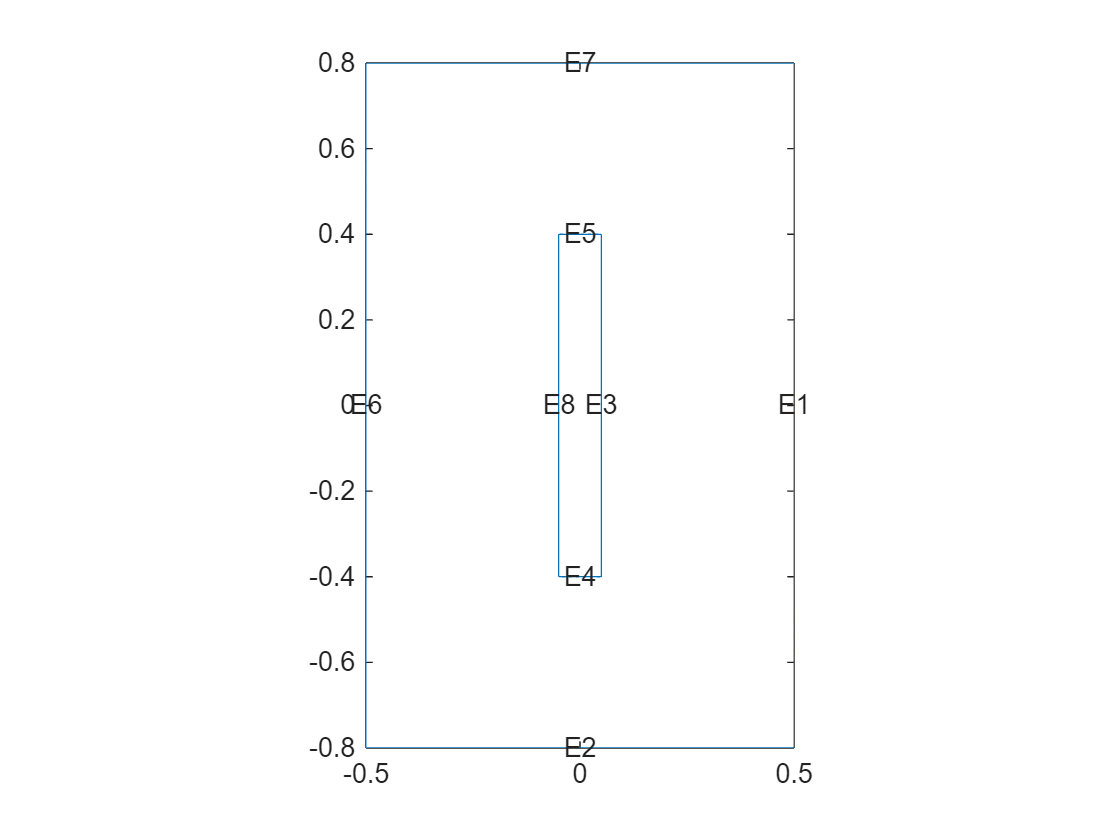

pdegplot(thermalmodel,"EdgeLabels","on")

Specify times to output the solution of the PDE.

solutionTimes = 0:0.01:0.1;

Solve the PDE in a loop to prepare dataset.

numObservations = height(initialAndBoundaryConditions);

initialCondition = initialAndBoundaryConditions.("Initial Condition");
dirichletBoundary = initialAndBoundaryConditions.E6_Temperature;
neumannBoundary = initialAndBoundaryConditions.E1_HeatFlux;
if ~isfile('data.mat')
parfor i = 1:numObservations-1    
    % Set initial condition
    thermalIC(thermalmodel,initialCondition(i));
    % Set left edge boundary condition
    thermalBC(thermalmodel, Edge=6, Temperature = dirichletBoundary(i));
    % Set right edge boundary condition.
    thermalBC(thermalmodel,Edge = 1, HeatFlux = neumannBoundary(i));
    % Solve the PDE
    solution{i} = solve(thermalmodel,solutionTimes);
end
save('data.mat',"solution")
else
    load('data.mat')
end

## Visualize a solution

Use `pdeplot` to plot a heat map of one of the solutions at time $t=0.1$.

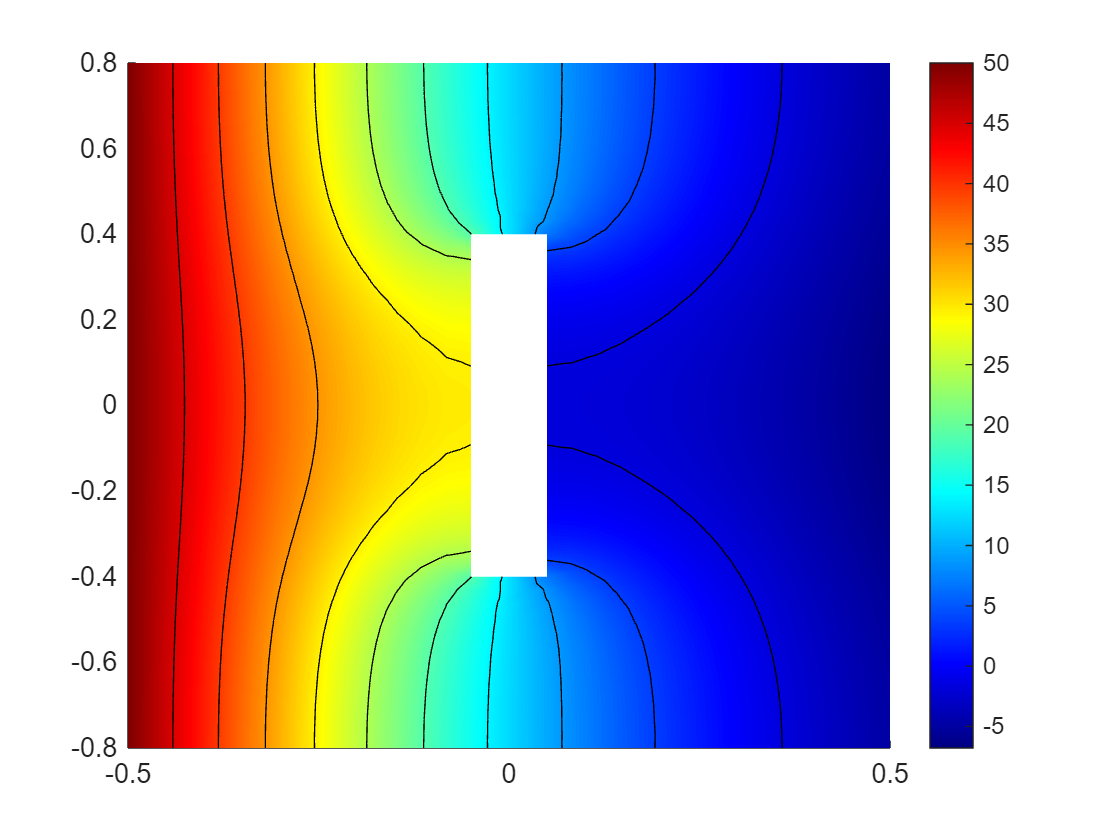

figure
pdeplot(thermalmodel,XYData=solution{1}.Temperature(:,end),Contour="on",ColorMap="jet");

## Create input and output features

Iterate over the solution data to create input features $(t,x,y,u_0,u_L,v_R)$ and output targets $u(t,x,y,u_0,u_L,v_R), \nabla u (t,x,y,u_0,u_L, v_R)$.

All solutions use the same mesh, so have the same $(x,y)$ coordinates.

x = thermalmodel.Mesh.Nodes.';
numNodes = size(x,1);
% Repeat solution times over node dimension
timesPerNode = reshape(repmat(solutionTimes(end),[numNodes,1]),[],1);
% Concatenate (t,x,y)
tx = [timesPerNode,x];
% Repeat over different initial and boundary conditions.
tx = repmat(tx,[numObservations,1]);
% Repeat each initial and boundary condition to each node.
u0 = initialCondition.';
u0 = repmat(u0,[numNodes,1]);
u0 = reshape(u0,[],1);
uL = dirichletBoundary.';
uL = repmat(uL,[numNodes,1]);
uL = reshape(uL,[],1);
vR = neumannBoundary.';
vR = repmat(vR,[numNodes,1]);
vR = reshape(vR,[],1);
% Concatenate (t,x,y,u0,uL,vR)
inputs = [tx,u0,uL,vR];
% Deal out the temperature u, and the gradients dudx and dudy for each
% solution at time t=0.1
[u,dudx,dudy] = cellfun(@(s) deal(s.Temperature(:,end),s.XGradients(:,end),s.YGradients(:,end)), solution, UniformOutput = false);
% Concatenate and flatten all the temperatures u and gradients dudx, dudy.
u = cat(2,u{:});
u = reshape(u, [], 1);
dudx = cat(2,dudx{:});
dudx = reshape(dudx,[],1);
dudy = cat(2,dudy{:});
dudy = reshape(dudy,[],1);
% Concatenate (u,dudx,dudy).
targets = [u,dudx,dudy];

## Create datastores

Put the training data into datastores to be minibatched later by `minibatchqueue`. Use `arrayDatastore` for in memory data.

inputds = arrayDatastore(inputs);
targetds = arrayDatastore(targets);
data = combine(inputds,targetds);

Create a train-test split.

totalNumObs = size(inputs,1);
idx = randperm(totalNumObs);
split = floor(0.9*totalNumObs);
trainIdx = idx(1:split);
testIdx = idx(split+1:end);
dataTrain = subset(data,trainIdx);
dataTest = subset(data,testIdx);

## Create minibatchqueue

minibatchSize = 1308*50;
mbqTrain = minibatchqueue(dataTrain, ...
    MiniBatchSize = minibatchSize,...
    MiniBatchFormat=["BC","BC"]);
mbqTest = minibatchqueue(dataTest, ...
    MiniBatchSize = minibatchSize,...
    MiniBatchFormat=["BC","BC"]);

## Define neural network

Use a multi-layer perceptron network to approximate the solution operator $(t,x,y,u_0,u_L,v_R) \rightarrow u(t,x,y,u_0,u_L,v_R)$. Use a `sigmoidLayer` as the last layer of the network to constrain the outputs to $[0,1]$. In the `model` function we will multiply the network output by $u_L$ so that the model output is in the range $[0,u_L]$. This corresponds with the intuition that with an initial temperature $u_L$ at one edge, and no heat sources, the temperature could not exceed $u_L$ at any point $\mathbf{x} \in \Omega$.

hiddenSize = 10;
activationLayer = @tanhLayer;
inputSize = size(inputs,2);
outputSize = 1;
layers = [
    featureInputLayer(inputSize)
    fullyConnectedLayer(hiddenSize)
    activationLayer()
    ...fullyConnectedLayer(hiddenSize)
    ...activationLayer()
    fullyConnectedLayer(hiddenSize)
    activationLayer()
    fullyConnectedLayer(outputSize)
    sigmoidLayer()];

## Define internal collocation points

A physics-informed neural network typically uses a PINN loss term. For the heat equation that is $\|\partial_t N_\theta - \Delta N_\theta\|_{L^2}$, i.e. a loss term that is the PDE itself. It's important to only evaluate this on the interior of the domain $\Omega$. This could be done by choosing only the mesh nodes corresponding to interior points, or we could arbitrarily sample the geometry's interior. Note that the PINN loss does not need training targets, so we can arbitrarily sample the interior of the domain. However note that the PINN loss alone makes no use of the initial conditions or boundary conditions, so either true solution data must be provided on the boundary to compute $\|u - N_\theta \|_{L^2 (\bar{\Omega})}$ including boundary points, or additional boundary points must be sampled and added as separate loss terms like $\|u - N_\theta \|_{L^2 (\partial \Omega) }$.

In this example we use the interior mesh nodes as collocation points for the PINN loss.

We can use the `findNodes` function to find all edge nodes, and remove these from the set of all nodes to leave only the interior nodes remaining.

% Set whether to train or not. If not, set it to false.
training = true;
% set to use GPU if it's available. 
% If you don't want to use it, edit this like gpuUse = false;
gpudevice = true;
% Choose only the mesh nodes corresponding to interior points
numEdges = thermalmodel.Geometry.NumEdges;
edgeNodeId = thermalmodel.Mesh.findNodes("region","Edge",1:numEdges);
interiorNodeId = 1:numNodes;
interiorNodeId(edgeNodeId) = [];
interiorNodes = thermalmodel.Mesh.Nodes(:,interiorNodeId);
if gpudevice == true
    interiorNodes = gpuArray(interiorNodes);
end
interiorNodes = dlarray(interiorNodes,"CB");

## Specify Training Options and Train

Train the model using the ADAM optimizer via `adamupdate`. Train for 1000 epochs. Use `dlaccelerate` to accelerate the evaluation of the `modelLoss` function.

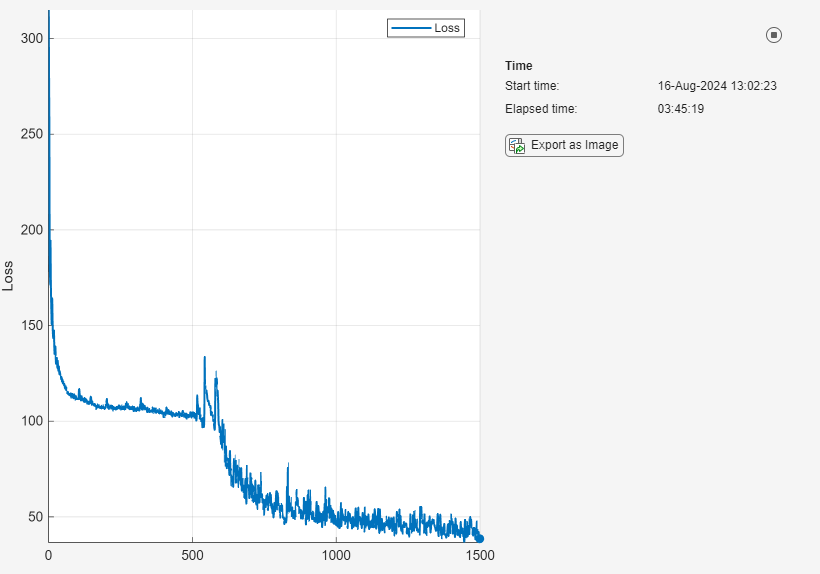

maxEpochs = 300;
avgG = [];
avgSqG = [];
inputRescale = dlarray([1;1;1;50;400;20]);
lossfcn = dlaccelerate(@modelLoss);
clearCache(lossfcn);
iter = 0;
learnRate=0.1;

if training==true
net = dlnetwork(layers);
monitor = trainingProgressMonitor(Metrics="Loss");
for epoch = 1:maxEpochs
    if monitor.Stop
        break
    end
    shuffle(mbqTrain);
    while mbqTrain.hasdata && ~monitor.Stop
        iter = iter+1;
        [input,target] = mbqTrain.next();
        [loss,grad] = dlfeval(lossfcn,input,net,target,inputRescale,interiorNodes);
        [net,avgG,avgSqG] = adamupdate(net,grad,avgG,avgSqG,iter,learnRate);
        monitor.recordMetrics(iter,Loss=loss);
    end
end
save("pinn.mat","net")
else
pinn = load("pinn_pre.mat");
net = pinn.net;
end

## Test on unseen initial and boundary condition

Use the last initial and boundary conditions to test the model.

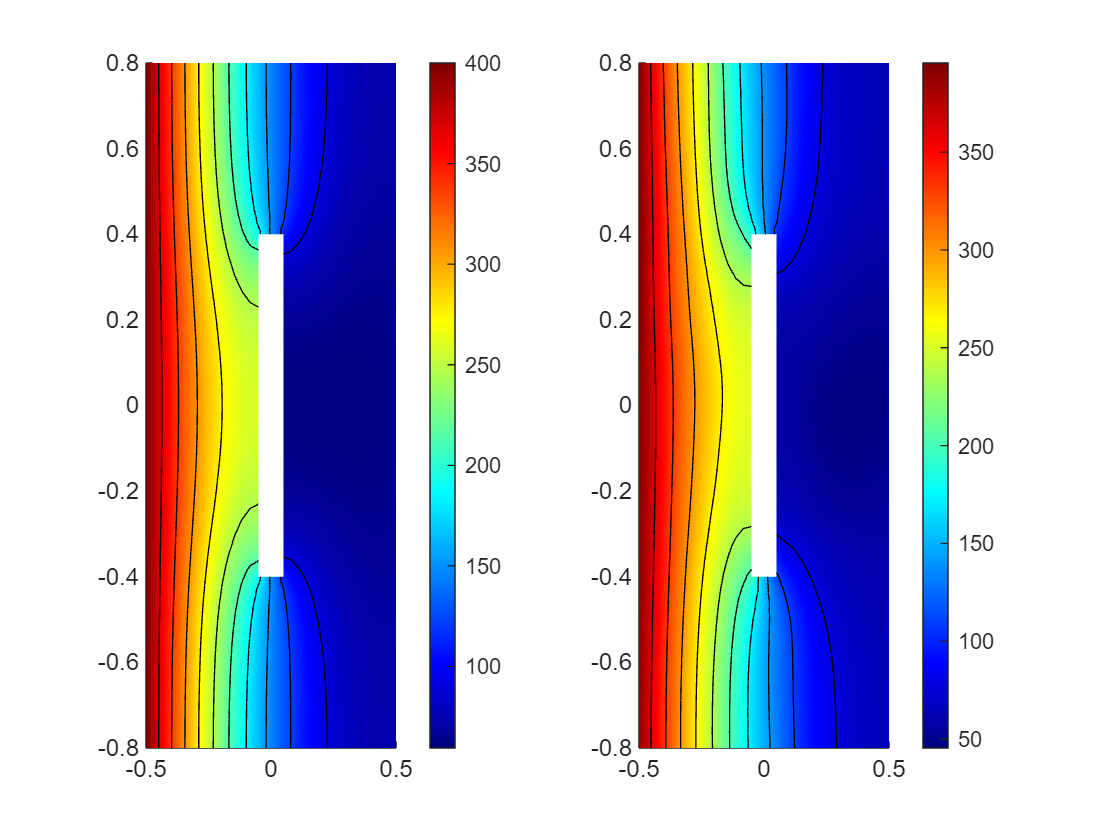

thermalIC(thermalmodel,initialCondition(end));
thermalBC(thermalmodel,Edge=6,Temperature=dirichletBoundary(end));
thermalBC(thermalmodel,Edge=1,HeatFlux=neumannBoundary(end));
result = solve(thermalmodel,[0,0.1]);
x = thermalmodel.Mesh.Nodes.';
numNodes = size(x,1);
t = repmat(0.1,[numNodes,1]);
u0 = repmat(initialCondition(end),[numNodes,1]);
uL = repmat(dirichletBoundary(end),[numNodes,1]);
vR = repmat(neumannBoundary(end),[numNodes,1]);
input = [t,x,u0,uL,vR];
% rescale
input = input./(extractdata(inputRescale.'));
upred = predict(net,input);
upred = upred.*uL;
figure;
subplot(1,2,1);
pdeplot(thermalmodel,XYData=result.Temperature(:,end),Contour="on",ColorMap="jet");
subplot(1,2,2);
pdeplot(thermalmodel,XYData=upred,Contour="on",ColorMap="jet");

## Define model loss

The model scales the inputs $(t,x,y,u_0,u_L,v_R)$ by constants $(c_t,c_x,c_y,c_{u_0}, c_{u_L}, c_{v_R})$, forwards these scaled inputs through `net`, and scales the output of `net` by $u_L$. This scaling helps training since the `net` by scaling the inputs down to a range more suitable for neural network training. The scaling factors for $u_0, u_L, v_R$ are compute from the maximum initial and boundary conditions.

The network approximates $N_\theta (t,x,y,u_0, u_L, v_R) \approx u(t,x,y,u_0,u_L,v_R)$. We compute a loss term `lossU` as $\|N_\theta - u \|_{L^2}$. We also have the values for $\nabla u (t,x,y,u_0,u_L,v_R)$ and can compute $\nabla N_\theta$ using `dlgradient`. This is used as a regularization term `lossGrad` which is $\|\nabla N_\theta - \nabla u \|_{L^2}$. Finally we add the physics-informed loss term $\|\partial t N_\theta - \Delta N_\theta\|_{L^2}$.

function [loss,gradient] = modelLoss(input,net,target,inputRescale,interiorNodes)
% Retain the boundary temperature
uL = input(5,:);
% Rescale the network inputs
input = input./inputRescale;
% Compute predicted temperature.
u = net.forward(input);
% Rescale
u = u.*uL;
% Compute gradients du/dx and du/dy
du = dlgradient(sum(u,2),input,RetainData=true);
dudxy = du([2,3],:);
% Compute losses
% loss of temperature u
lossU = sqrt(l2loss(u,target(1,:)));
% loss of gradients du/dx and du/dy
lossGrad = sqrt(l2loss(dudxy,target([2,3],:)));
loss = lossU + lossGrad;
% Compute PINN loss
% Append arbitrary IC and BC to interiorNodes
numInteriorNodes = size(interiorNodes,2);
arbitraryICBCSample = randperm(size(input,2));
arbitraryICBCSample = arbitraryICBCSample(1:numInteriorNodes);
interiorInput = cat(1,input(1,arbitraryICBCSample),interiorNodes,input(4:end,arbitraryICBCSample));
uL = interiorInput(5,:);
interiorInput = interiorInput./inputRescale;
% Forward the interior nodes
uinterior = net.forward(interiorInput);
uinterior = uinterior.*uL;
du = dlgradient(sum(uinterior,2),interiorInput,RetainData=true);
dudx = du(2,:);
dudy = du(3,:);
dudt = du(1,:);
% 
d2udx = dlgradient(sum(dudx,2),interiorInput,RetainData = true);
d2udy = dlgradient(sum(dudy,2),interiorInput,RetainData = true);
laplacianU = d2udx(2,:) + d2udy(3,:);
lossPinn = sqrt(l2loss(dudt, laplacianU));
% the loss has loss of temperature, grandient du/dx and du/dy, and pinn 
loss = loss + lossPinn;
% Compute gradients
gradient = dlgradient(loss,net.Learnables);
end

Copyright (c) 2024, The MathWorks, Inc.